## Dataset Preparation from Raw  Signals

clear
warning off
global axisValue

data_dir = fullfile(pwd, 'Data');
folder_list = dir([data_dir filesep 'case*']);

fs = 20000;% sensor sampling frequency
frameWindow = 2000;   % define window frames
win_len = frameWindow./fs;% Window length for feature extraction in seconds

% Specify the overlap between adjacent windows for feature extraction in percentage
win_overlap = 0;

axisValue = 3;  %axisValue=1、2 or 3  presents signal from "X-axis"、"Y-axis"、"Z-axis"

trainingtable=table();
validationtable=table();
T=table();
V=table();

for ifolder = 1:length(folder_list)
%     T_table = table();
%     V_table = table();
    foldername = folder_list(ifolder).name;
    disp(['Processing files from folder: ' foldername])
    current_folder = [data_dir filesep foldername];
    training_fds = fileDatastore(current_folder, 'ReadFcn', @csvread, 'FileExtensions', '.csv', 'IncludeSubfolders', 1);
    [T_table,V_table]= extractsignaldata(training_fds, win_len, win_overlap,foldername);

    for i=1:size(T_table,1)
        rxI = T_table.signal{i,1};
        rxQ = abs(fft(rxI));
        T_table.signal{i,1} = cat(1,squeeze(rxI),squeeze(rxQ));
    end

    for i=1:size(V_table,1)
        rxI = V_table.signal{i,1};
        rxQ = abs(fft(rxI));
        V_table.signal{i,1} = cat(1,squeeze(rxI),squeeze(rxQ));
    end
    T=[T;T_table];
    V=[V;V_table];
end

Processing files from folder: case1
Processing files from folder: case2
Processing files from folder: case3
Processing files from folder: case4
Processing files from folder: case5


% random distribution of training and validation samples
n=randperm(size(T,1));
for i=1:size(T,1)
    trainingtable{i,:} = T{n(i),:};
end
trainingtable.Properties.VariableNames={'signal','class'};
n=randperm(size(V,1));
for i=1:size(V,1)
    validationtable{i,:} = V{n(i),:};
end
validationtable.Properties.VariableNames={'signal','class'};

trainingtable.class=categorical(trainingtable.class);
validationtable.class=categorical(validationtable.class);


## Define ConvLSTM Network Architecture

dropoutRate = 0.5;
numModulationTypes=5;

netWidth = 1;
filterSize = [1 8];
poolSize = [1 2];
modClassNet = [
    sequenceInputLayer([2 frameWindow 1],'Name','input')
    sequenceFoldingLayer('Name','fold')
    convolution2dLayer(filterSize, 16*netWidth, 'Padding', 'same', 'Name', 'CNN1')
    batchNormalizationLayer('Name', 'BN1')
    reluLayer('Name', 'ReLU1')
    maxPooling2dLayer(poolSize, 'Stride', [1 2], 'Name', 'MaxPool1')
    convolution2dLayer(filterSize, 24*netWidth, 'Padding', 'same', 'Name', 'CNN2')
    batchNormalizationLayer('Name', 'BN2')
    reluLayer('Name', 'ReLU2')
    maxPooling2dLayer(poolSize, 'Stride', [1 2], 'Name', 'MaxPool2')
    sequenceUnfoldingLayer('Name','unfold')
    flattenLayer('Name','flatten')
    lstmLayer(16,"OutputMode","last",'Name','lstm2')
    dropoutLayer(dropoutRate,'Name', 'Dropout')
    fullyConnectedLayer(numModulationTypes, 'Name', 'FC1')
    softmaxLayer('Name', 'SoftMax')
    classificationLayer('Name', 'Output') ]

modClassNet =   17×1 Layer array with layers:

     1   'input'      Sequence Input          Sequence input with 2×2000×1 dimensions
     2   'fold'       Sequence Folding        Sequence folding
     3   'CNN1'       Convolution             16 1×8 convolutions with stride [1  1] and padding 'same'
     4   'BN1'        Batch Normalization     Batch normalization
     5   'ReLU1'      ReLU                    ReLU
     6   'MaxPool1'   Max Pooling             1×2 max pooling with stride [1  2] and padding [0  0  0  0]
     7   'CNN2'       Convolution             24 1×8 convolutions with stride [1  1] and padding 'same'
     8   'BN2'        Batch Normalization     Batch normalization
     9   'ReLU2'      ReLU                    ReLU
    10   'MaxPool2'   Max Pooling             1×2 max pooling with stride [1  2] and padding [0  0  0  0]
    11   'unfold'     Sequence Unfolding      Sequence unfolding
    12  


lgraph = layerGraph(modClassNet);
lgraph = connectLayers(lgraph,'fold/miniBatchSize','unfold/miniBatchSize');


## Define Triaining Options and Train Network

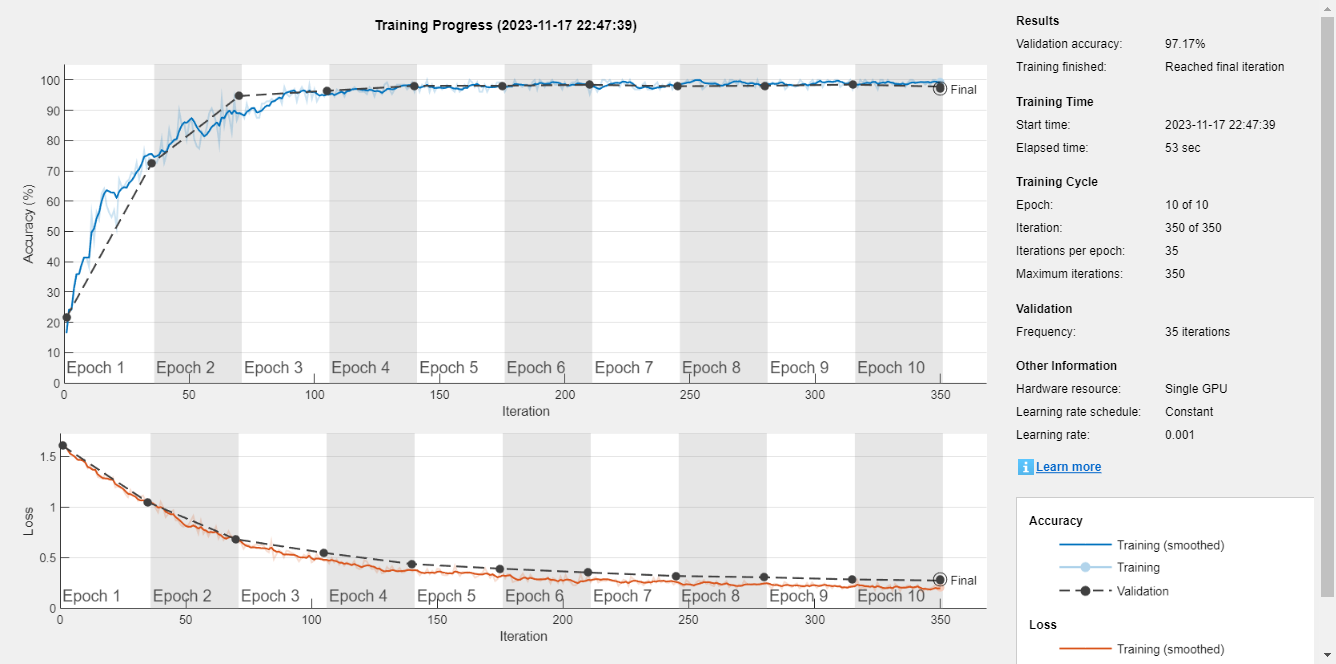

maxEpochs = 10;
miniBatchSize = 128;
validationFrequency = floor(numel(trainingtable.signal)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',{validationtable.signal,validationtable.class}, ...
    'ValidationFrequency',validationFrequency, ...
    'ExecutionEnvironment', 'gpu');

trainedNet = trainNetwork(trainingtable.signal,trainingtable.class,lgraph,options);

## Data Validation and Confusion Matrix


validationPred = classify(trainedNet,validationtable.signal);
validationAccuracy = mean(validationPred == validationtable.class);
disp("Valadition accuracy: " + validationAccuracy*100 + "%")

Valadition accuracy: 97.1667%


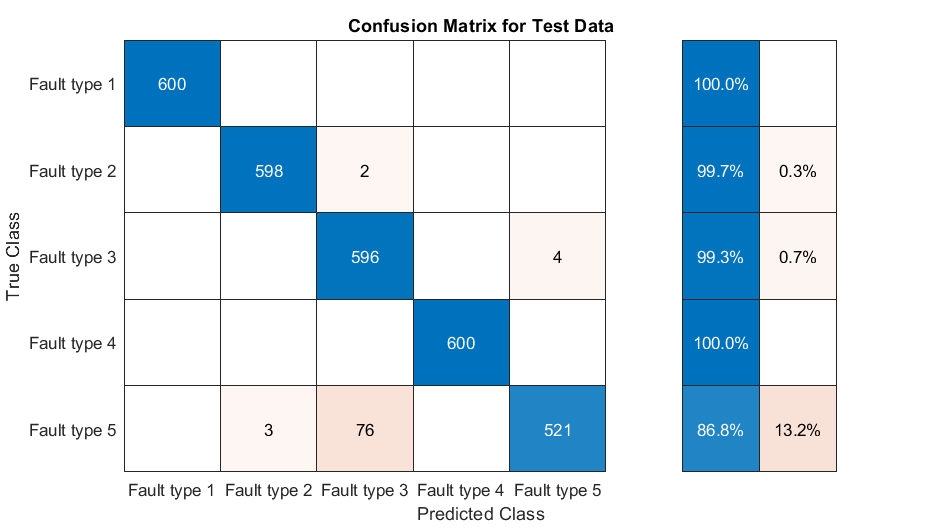


figure
cm = confusionchart(validationtable.class, validationPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 740 424];

function [signal_table_training,signal_table_validation] = extractsignaldata(fds, window_length, window_overlap, foldername)

warning off
global axisValue

overlap_length = window_length * window_overlap / 100;
step_length = window_length - overlap_length;

signal_table_validation = table();
signal_table_training = table();

labelMap = containers.Map('KeyType','char','ValueType','char');
keySet = {'case1','case2','case3','case4','case5'};
valueSet = {'Fault type 1','Fault type 2','Fault type 3','Fault type 4','Fault type 5'};
labelMap = containers.Map(keySet,valueSet);

while hasdata(fds)
    %     extract signals and file path
    [vibrition,info] = read(fds);
    signal = vibrition(:,axisValue);

    fs = 20000;
    %     extract filename
    [~,fname,~] = fileparts(info.Filename);
    %     numbers of frames per file
    number_of_windows = floor(( size(signal,1) - overlap_length*fs) / (fs * step_length));
    signal_validation_table = table();
    signal_training_table = table();
    speed=str2num(fname(end-3:end));
    
    if speed==1370|speed==1870         %     extract speed 1370 and 1870 for validation data
        for iwin = 1:number_of_windows
            current_start_sample = (iwin - 1) * fs * step_length + 1;
            current_end_sample = current_start_sample + window_length * fs - 1;
            current_signal = signal(current_start_sample:current_end_sample,:);
            signal_validation_table.signal{iwin, 1} = current_signal';
            % Assign class label to the observation
            if iwin == 1
                signal_validation_table.class = {labelMap(foldername)};
            else
                signal_validation_table.class{iwin, :} = labelMap(foldername);
            end
        end
        signal_table_validation = [signal_table_validation; signal_validation_table];
    else

        for iwin = 1:number_of_windows
            current_start_sample = (iwin - 1) * fs * step_length + 1;
            current_end_sample = current_start_sample + window_length * fs - 1;
            current_signal = signal(current_start_sample:current_end_sample,:);
            signal_training_table.signal{iwin, 1} = current_signal';
            % Assign class label to the observation
            if iwin == 1
                signal_training_table.class = {labelMap(foldername)};
            else
                signal_training_table.class{iwin, :} = labelMap(foldername);
            end
        end
        signal_table_training = [signal_table_training; signal_training_table];
    end
end
end